# Solution to *Tallest Building Record* exercise

## Initialize data

Load list of tallest buildings

load tallest_bldgs

Create vector for years spanning the range in the data set

y = (min(buildings.Year):max(buildings.Year))';
n = length(y);

Create a table to hold the results. Names and heights are left unknown.

hrecord = table(y,strings(n,1),NaN(n,1),'VariableNames',["Year","Name","Height"]);

## Determine tallest building for each year

Loop over years, extract the table of buildings in existence up to that year, find the building with the maximum height from that table.

for k = 1:n
    b = buildings(buildings.Year <= y(k),:);
    [~,idx] = max(b.Height);
    hrecord(k,["Name","Height"]) = b(idx,["Name","Height"]);
end

## Visualize tenures

Count the number of occurrences of each building to determine the number of years as the tallest

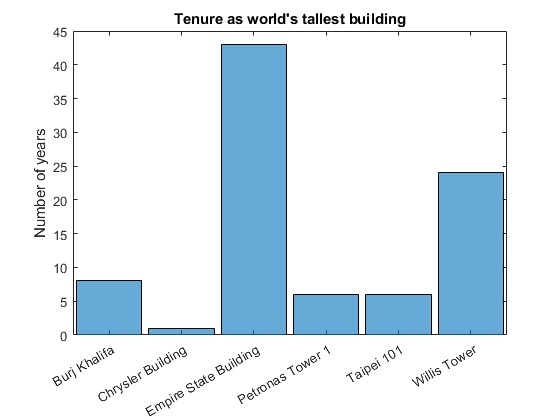

histogram(categorical(hrecord.Name))
ylabel("Number of years")
title("Tenure as world's tallest building")